%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% This notebook explores ways to represent graphically the SCANDI fpi data
% and the SCANDI zones. This is just a an exploratory MATLAB notebook.

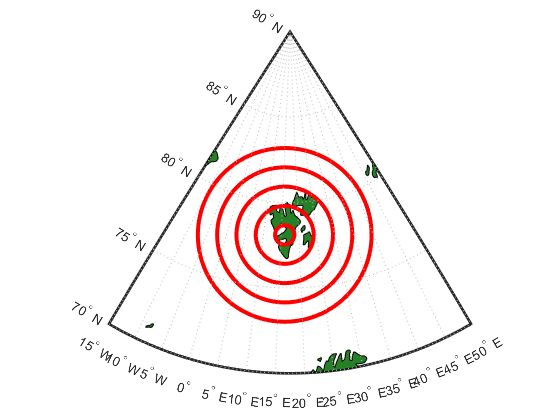


%%% topograph of Svalbard

worldmap([70 90], [-15 50])
load coastlines;
%plotm(coastlat, coastlon , "b")
geoshow('landareas.shp', 'FaceColor',[0.15 0.5 0.15])
geoshow('worldcities.shp')
%geobubble(78.1,16.0)
circlem(78.1,16.0,r,'edgecolor', 'red', 'linewidth', 3)
hold off

%%% drawing the circles on cartesian coordinates

fpi_loc = [78.1, 16.0];
r = [62.82272976
188.4681893
314.1136488
439.7591083
565.4045678
];
N = [6,18,18,18,18];

figure;
circle(16.0,78.1,565.40,18)

ans =   handle to deleted Line


hold on
circle(16.0,78.1,439.75,18)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×180 double]
              YData: [1×180 double]
              ZData: [1×0 double]

  Show all properties


hold on
circle(16.0,78.1,314.11,18)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×180 double]
              YData: [1×180 double]
              ZData: [1×0 double]

  Show all properties


hold on
circle(16.0,78.1,188.46,6)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×60 double]
              YData: [1×60 double]
              ZData: [1×0 double]

  Show all properties


hold on 
circle(16.0,78.1,62.8,0)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


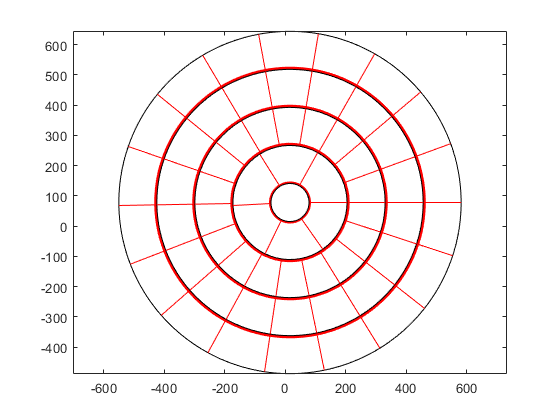

hold off

%%% projecting cartesian circles onto lat long coordinate system


worldmap([70 90], [-15 50])

Error using matlab.graphics.axis.GeographicAxes/set
Unrecognized property DataAspectRatio for class GeographicAxes.

Error in axesm>setgca (line 799)
set(gca, ...

Error in axesm (line 182)
        setgca(mstruct)

Error in 

geoshow('landareas.shp', 'FaceColor',[0.15 0.5 0.15])
hold on
% circle(78.1, 16.0,565.40,18)
% hold on
% circle(78.1, 16.0,439.75,18)
% hold on
% circle(78.1, 16.0,314.11,18)
% hold on
% circle(78.1, 16.0,188.46,6)
% hold on 


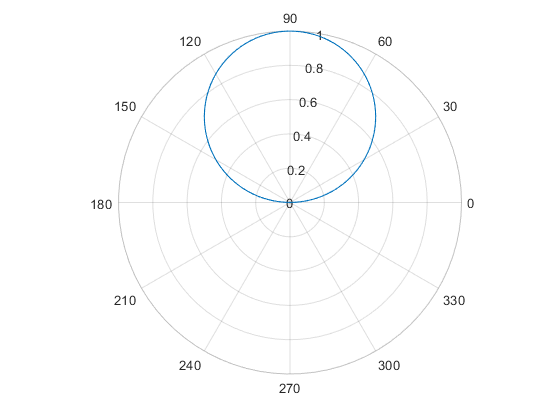

theta = linspace(0,2*pi);
rho = 1*sin(theta);
polarplot(theta,rho)

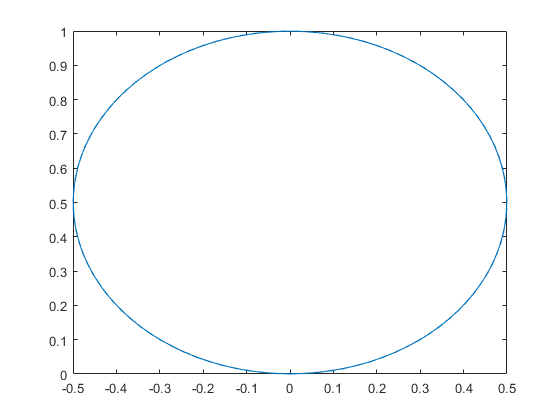

[x,y] = pol2cart(theta,rho);
plot(x,y)

theta = deg2rad(14.1)

theta = 0.2461

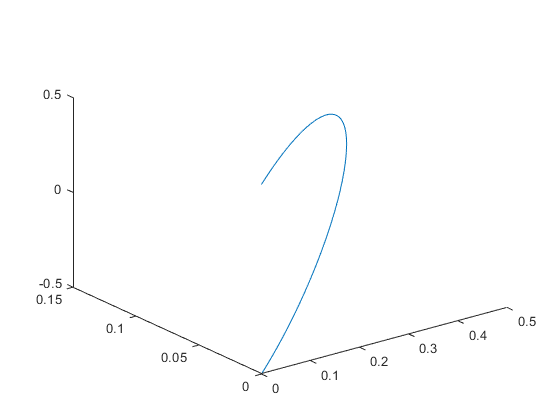

phi = linspace(-pi/2, pi/2);
[theta, phi] = meshgrid(theta, phi);
rho = 0.5;
[x,y,z] = sph2cart(theta,phi,rho);
plot3(x,y,z)
hold off

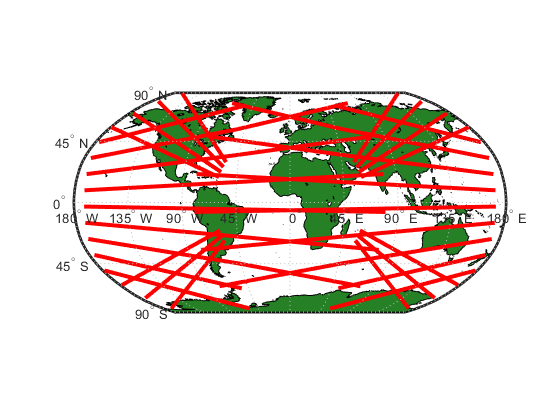

worldmap("World")
geoshow('landareas.shp', 'FaceColor',[0.15 0.5 0.15])
hold on
a = linspace(0, 2*pi, 100);
xunits = r*cos(a) + 0;
yunits = r*sin(a) + 0;
h = plotm(xunits, yunits, 'Color', 'r', 'LineWidth', 3);

fillm(xunits,yunits, "w");

Array indices must be positive integers or logical values.

Error in map.internal.clip.closePolygonInRectangle

Error in map.internal.clip.closePolygonInRectangle

Error in map.internal.clip.closePolygonInRectangle

Error in map.internal.clip.closePolygonInRectangle

Error in map.internal.clip.closePolygonInRectangle

Error in trimPolygonToQuadrangle>snapAndClose (line 132)
[x, y] = map.internal.clip.closePolygonInRectangle( ...

Error in 

figure;
load coastlines.mat;
[X,Y]= meshgrid(-179:180, -89:90);
plot(coastlon, coastlat,"r","LineWidth",2)
box on
%geoshow('landareas.shp', 'FaceColor',[0.15 0.5 0.15])
%circle(16.0,78.1, 4,0)
xlim([-15 50])
ylim([70 90])
xlabel("longitude")
ylabel("latitude")
grid on;
hold on
circle(16.0,78.1,2,0)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


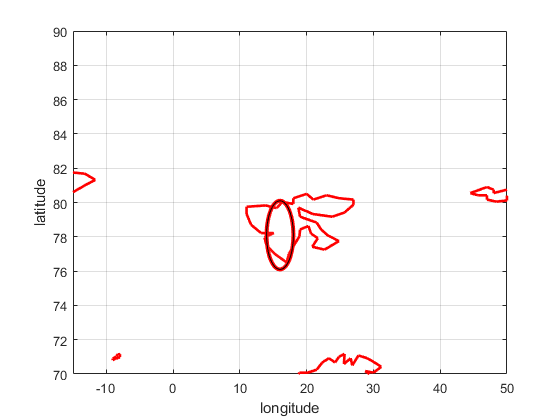

hold off


%% doesnt match because r in meters and lat lon should be in degrees !!
lla2eci([78.1,16.0,240],[2020 1 1 0 0 0])

ans = 	1.0e+06 *

   -0.5638    1.1872    6.2206


figure;
axesm("gstereo","MapLatLimit",[65 90], "MapLonLimit",[-15 50])
xticks('auto')
yticks('auto')
geoshow('landareas.shp', 'FaceColor',[0.15 0.5 0.15])
hold on
circle(16.0,78.1,62.8,0)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


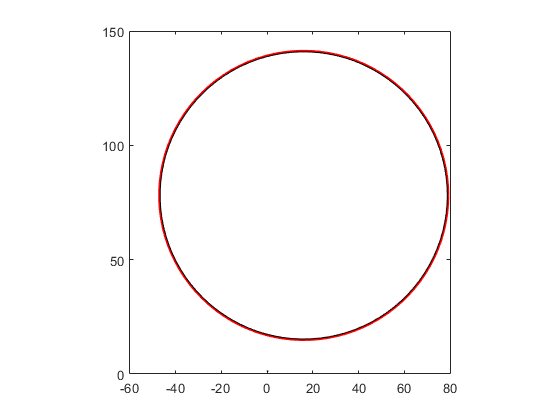

hold off

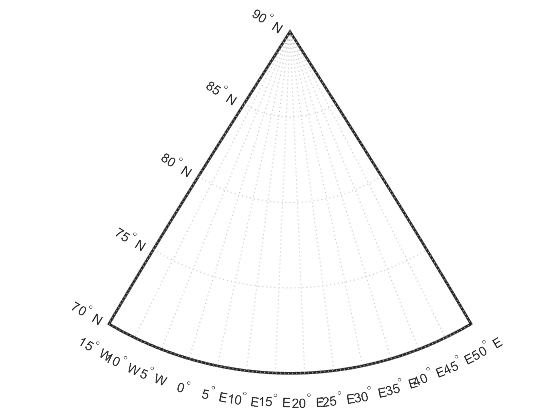

worldmap([70 90], [-15 50])

hold on
theta = linspace(0,2*pi);
rho = 1*sin(theta);
polarplot(theta,rho)

Adding polar plot to axes is not supported.

[x,y] = pol2cart(theta,rho);
plot(x,y)
hold off






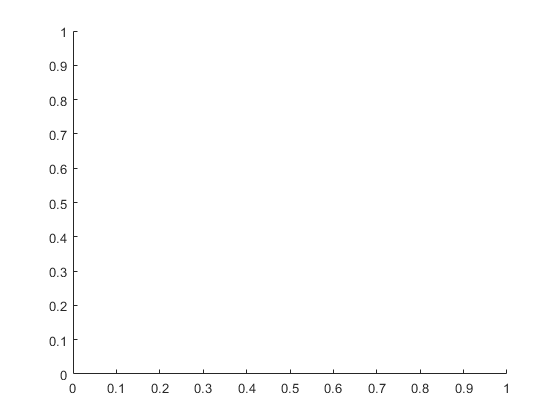

hold off

geobasemap basemap

Error using geobasemap>parseInputs (line 78)
Unable to use geobasemap. Current axes or chart is not geographic.

Error in geobasemap (line 30)
    [gx, basemap, usingBasemapSyntax] = parseInputs(varargin);

geobasemap colorterrain

figure;
R = 2;
C = [78.1, 16.0];
th = linspace(0,2*pi);
x = C(2) + R*cos(th)

x =    18.0000   17.9960   17.9839   17.9639   17.9359   17.9001   17.8567   17.8059   17.7477   17.6825   17.6105   17.5321   17.4475   17.3570   17.2611   17.1601   17.0545   16.9445   16.8308   16.7138   16.5938   16.4715   16.3473   16.2217   16.0952   15.9683   15.8415   15.7154   15.5904   15.4671   15.3459   15.2273   15.1119   15.0000   14.8922   14.7888   14.6903   14.5971   14.5095   14.4279   14.3526   14.2840   14.2223   14.1678   14.1206   14.0810   14.0491   14.0251   14.0091   14.0010


y = C(1) +R*sin(th)

y =    78.1000   78.2268   78.3532   78.4785   78.6023   78.7241   78.8433   78.9596   79.0724   79.1813   79.2858   79.3856   79.4802   79.5692   79.6523   79.7292   79.7995   79.8629   79.9193   79.9683   80.0098   80.0436   80.0696   80.0877   80.0977   80.0997   80.0937   80.0796   80.0576   80.0277   79.9900   79.9447   79.8920   79.8321   79.7651   79.6915   79.6115   79.5254   79.4335   79.3363   79.2341   79.1274   79.0165   78.9019   78.7840   78.6635   78.5406   78.4160   78.2901   78.1635


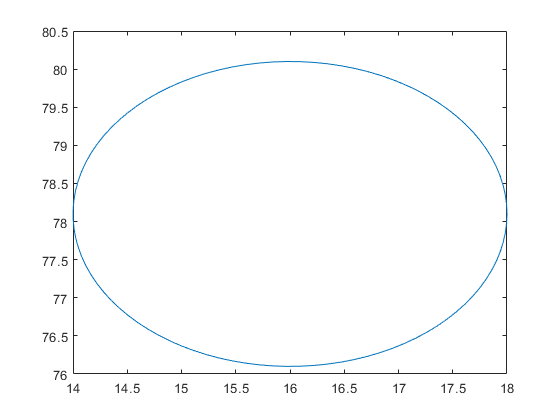

plot(x,y)

% hold off
% figure;
% worldmap world
% hold on 
% plot(x,y)
% hold off

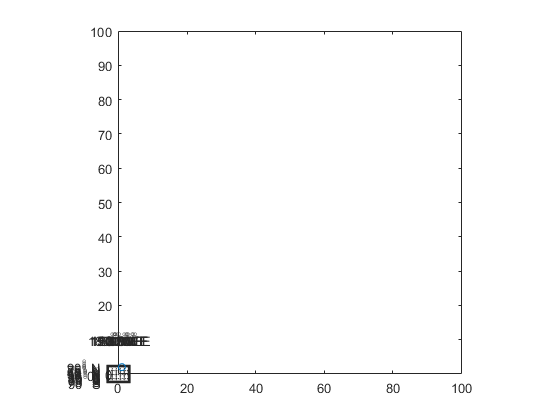

figure;
axesm miller;
framem on;
gridm on;
mlabel on;
plabel on;
showaxes;
grid off;
xlim([0 100])
ylim([0 100])
plot(x,y)
hold off

geobasemap("topographic")

Error using geobasemap>parseInputs (line 78)
Unable to use geobasemap. Current axes or chart is not geographic.

Error in geobasemap (line 30)
    [gx, basemap, usingBasemapSyntax] = parseInputs(varargin);

geolimits([70 90], [-15 50])
geoplot(fpi_loc(1),fpi_loc(2))


a = linspace(0, 2*pi, 6*10);
x = 0

x = 0

y = 0

y = 0

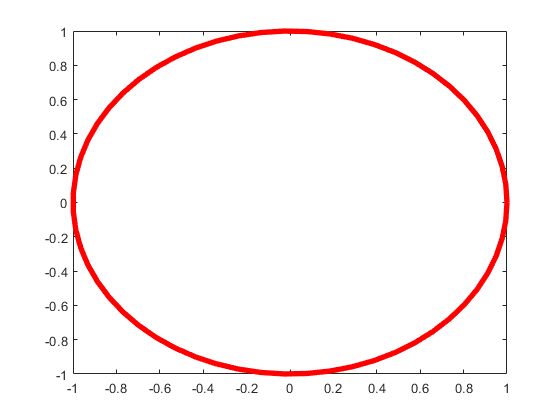

xunits = 1*cos(a) + x;
yunits = 1*sin(a) + y;
figure(1)
h = plot(xunits, yunits, 'Color', 'r', 'LineWidth', 4);

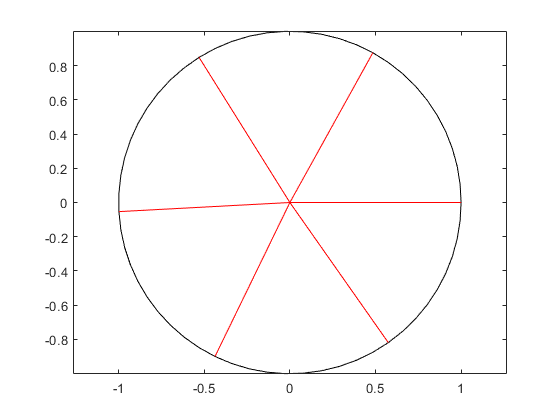

fill(xunits,yunits, "w");
hold on
plot([zeros(1,6); xunits(1:10:end)], [zeros(1,6); yunits(1:10:end)],'color', 'r');
hold off
axis equal

figure(1);
a = linspace(0, 2*pi, 100);
x = 16

x = 16

y = 78.1

y = 78.1000

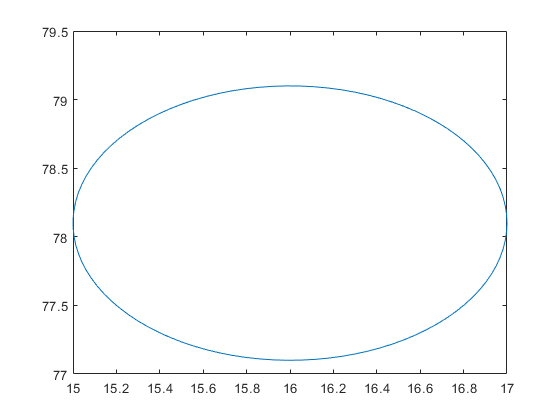

xunits = 1*cos(a) + x;
yunits = 1*sin(a) + y;
plot(xunits,yunits)

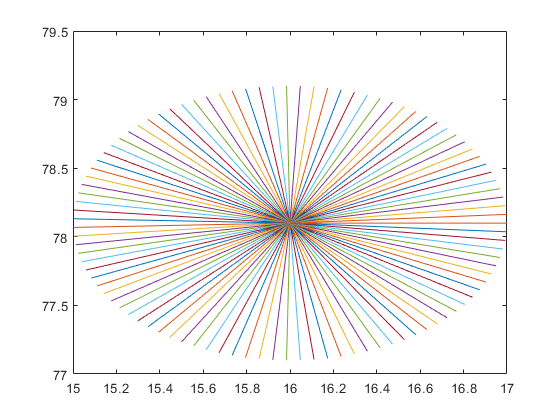

figure(1);
for i=1:numel(xunits)
    plot([x xunits(i)],[y yunits(i)])
    hold on
end

theta= 60

theta = 60

y0 = fpi_loc(1)

y0 = 78.1000

x0 = fpi_loc(2)

x0 = 16

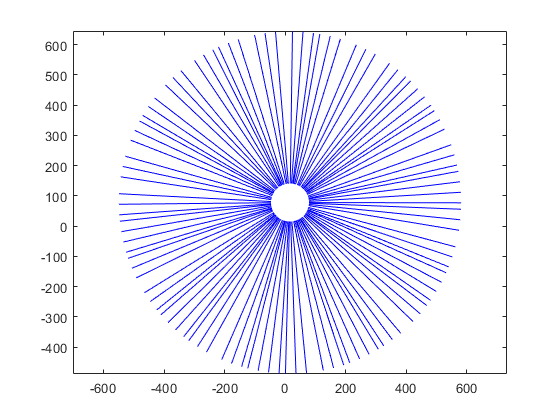

a1 = 2*pi*rand;  % A random direction
a2 = a1 + theta;
t = linspace(a1,a2);
x = x0 + r*cos(t);
y = y0 + r*sin(t);
plot(x,y,'b')
axis equal

x = 16

x = 16

y = 78.1

y = 78.1000

N = 6

N = 6

r = 62.8

r = 62.8000

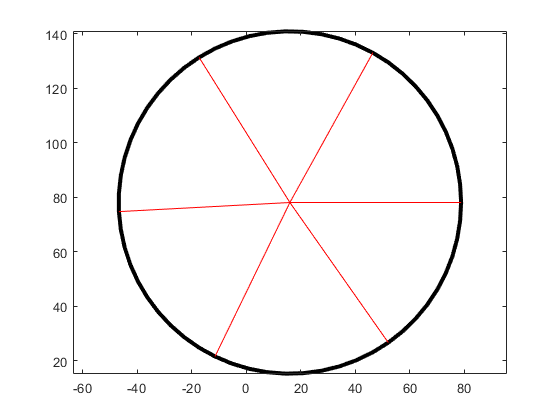

a = linspace(0, 2*pi, N*10);
xunits = r*cos(a) + x;
yunits = r*sin(a) + y;
figure;
%plot(xunits, yunits, 'Color', 'r', 'LineWidth', 4);
fill(xunits,yunits, "w","LineWidth", 3);
hold on
plot([repmat(x,1,N); xunits(1:10:end)], [repmat(y,1,N); yunits(1:10:end)],'color', 'r');
hold off
axis equal

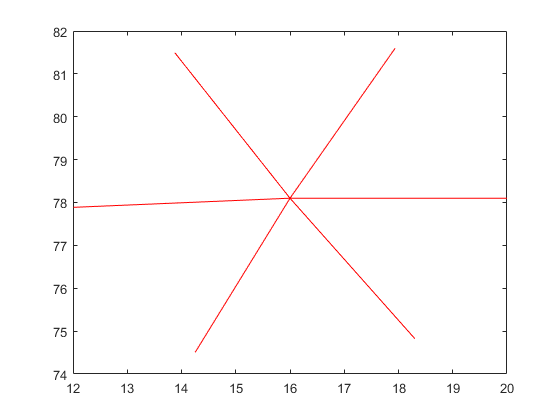

figure;
plot([repmat(x,1,N); xunits(1:10:end)], [repmat(y,1,N); yunits(1:10:end)],'color', 'r');

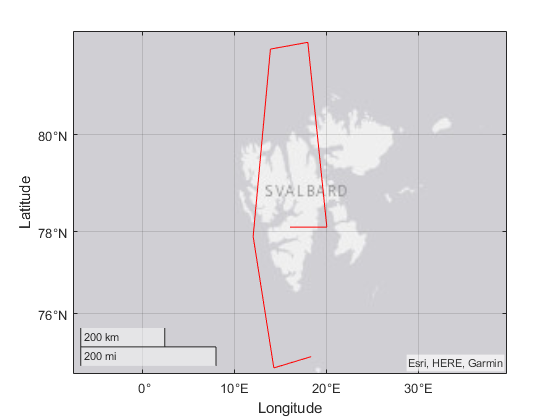

figure;
geoplot([repmat(y,N,1); (yunits(1:10:end))'], [repmat(x,N,1); (xunits(1:10:end))'],'color', 'r');
hold off

lati = [];
longi = [];


t =    78.1000   81.5991   81.4909   77.8871   74.5028   74.8268


for i=[1:length(t)]
    t(i) = lati;
end

Unable to perform assignment because the left and right sides have a different number of elements.

%%% putting together onto one array (make this a function)

lat1 = circshift(lat,76)

lat1 =    78.0718
   78.1319
   78.1918
   78.2508
   78.3082
   78.3633
   78.4155
   78.4642
   78.5087
   78.5485


lon1 = circshift(lon,76);

t1 = repmat(y,N,1)'

t1 =    78.1000   78.1000   78.1000   78.1000   78.1000   78.1000


ty = (lat1(1:10:end))'

ty =    78.0718   78.5830   78.6119   78.1319   77.6255   77.5962



out0 = [ty(rem(0:numel(t1)-1,numel(ty))+1);t1];
outy = out0(:)'

outy =    78.0718   78.1000   78.5830   78.1000   78.6119   78.1000   78.1319   78.1000   77.6255   78.1000   77.5962   78.1000



t2 = repmat(x,N,1)'

t2 =     16    16    16    16    16    16


tx = (lon1(1:10:end))'

tx =    13.2675   14.5514   17.1820   18.7384   17.4570   14.7876



out0 = [tx(rem(0:numel(t2)-1,numel(tx))+1);t2];
outx = out0(:)'

outx =    13.2675   16.0000   14.5514   16.0000   17.1820   16.0000   18.7384   16.0000   17.4570   16.0000   14.7876   16.0000


figure;
gx = geoaxes('Basemap',"bluegreen")

gx =   GeographicAxes with properties:

     Basemap: 'bluegreen'
    Position: [0.1300 0.1100 0.7750 0.8150]
       Units: 'normalized'

  Show all properties


geolimits([66.6 83.9],[-30.7 68.2])
hold on
[lat,lon] = scircle1(78.1,16,62.8,[],earthRadius("km"),"degrees",60)

lat =    78.6648
   78.6614
   78.6514
   78.6348
   78.6119
   78.5830
   78.5485
   78.5087
   78.4642
   78.4155


lon =    16.0000
   16.3053
   16.6067
   16.9002
   17.1820
   17.4486
   17.6967
   17.9233
   18.1258
   18.3020


[outy,outx] = circle_sectors(lat,lon,6)

lat1 =    78.0718
   78.1319
   78.1918
   78.2508
   78.3082
   78.3633
   78.4155
   78.4642
   78.5087
   78.5485


t1 =    78.1000   78.1000   78.1000   78.1000   78.1000   78.1000


ty =    78.0718   78.5830   78.6119   78.1319   77.6255   77.5962


outy =    78.0718   78.1000   78.5830   78.1000   78.6119   78.1000   78.1319   78.1000   77.6255   78.1000   77.5962   78.1000


t2 =     16    16    16    16    16    16


tx =    13.2675   14.5514   17.1820   18.7384   17.4570   14.7876


outx =    13.2675   16.0000   14.5514   16.0000   17.1820   16.0000   18.7384   16.0000   17.4570   16.0000   14.7876   16.0000


outy =    78.0718   78.1000   78.5830   78.1000   78.6119   78.1000   78.1319   78.1000   77.6255   78.1000   77.5962   78.1000


outx =    13.2675   16.0000   14.5514   16.0000   17.1820   16.0000   18.7384   16.0000   17.4570   16.0000   14.7876   16.0000


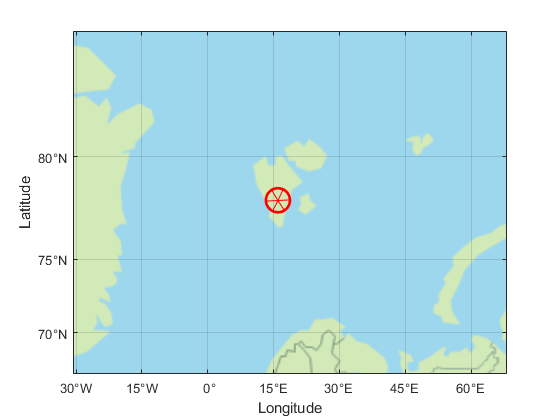

geoplot(lat,lon,"r","LineWidth", 2)
hold on 
geoplot(outy,outx,'color', 'r');
hold on

quiverm(y,x,10,10)

Error using gcm (line 25)
Not a map axes.

Error in quiverm (line 88)
    mstruct = gcm;

%%%%%%%%%%%%%%%%%%%%% lets plot some data on to these scandi zones  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure;
circle(16.0,78.1,565.40,18)

ans =   handle to deleted Line


hold on
circle(16.0,78.1,439.75,18)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×180 double]
              YData: [1×180 double]
              ZData: [1×0 double]

  Show all properties


hold on
circle(16.0,78.1,314.11,18)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×180 double]
              YData: [1×180 double]
              ZData: [1×0 double]

  Show all properties


hold on
circle(16.0,78.1,188.46,6)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×60 double]
              YData: [1×60 double]
              ZData: [1×0 double]

  Show all properties


hold on 
circle(16.0,78.1,62.8,0)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties


hold off

%%% importing data for 12.0856
winds = readtable("WNM14C21_windfit.xlsx","Sheet","example data at 12.0856 UT");

zonal = winds.zonalWindComponent_m_s_;
merid = winds.meridionalWindComponent_m_s_;
dz = winds.zonalDistances_km_;
dm = winds.meridionalDistances_km_;
angle = winds.adjustSectorAngleToBeContinuousForPlotting;

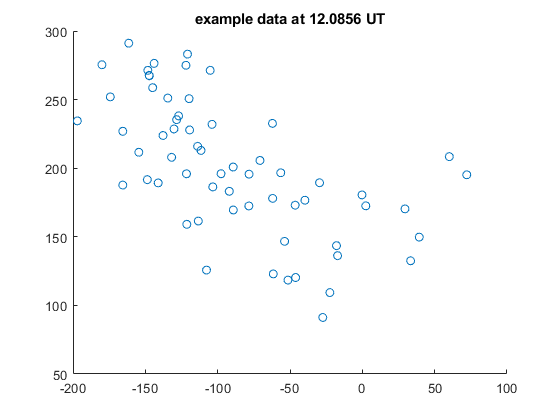

figure;
scatter(zonal,merid)
title("example data at 12.0856 UT")

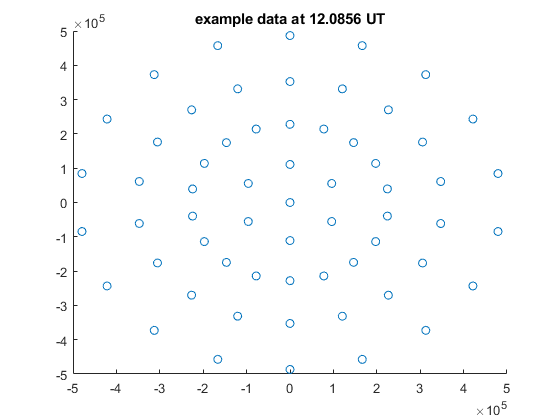

figure;
scatter(dz,dm)
title("example data at 12.0856 UT")

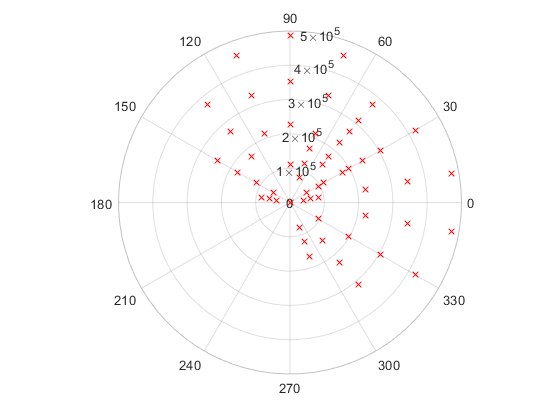

%%% in polar coords

polarplot(deg2rad(angle),dm,"x","Color","r")
hold on
polarplot(deg2rad(angle),dz,"x","Color","r")
hold off

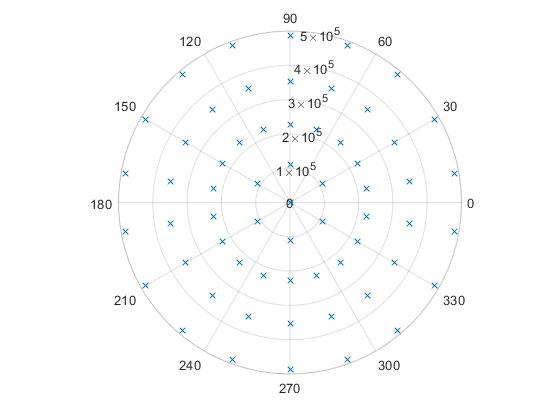

sqrt(dm.^2+dz.^2);
polarplot(deg2rad(angle),sqrt(dm.^2+dz.^2),"x");

dz/1000;

%%%%% plotting the wind vectors on top of the scandi zones


figure;
circle(0,0,565.40,18)

ans =   handle to deleted Line

hold on
circle(0,0,439.75,18)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×180 double]
              YData: [1×180 double]
              ZData: [1×0 double]

  Show all properties

hold on
circle(0,0,314.11,18)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×180 double]
              YData: [1×180 double]
              ZData: [1×0 double]

  Show all properties

hold on
circle(0,0,188.46,6)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×60 double]
              YData: [1×60 double]
              ZData: [1×0 double]

  Show all properties

hold on 
circle(0,0,62.8,0)

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×100 double]
              YData: [1×100 double]
              ZData: [1×0 double]

  Show all properties

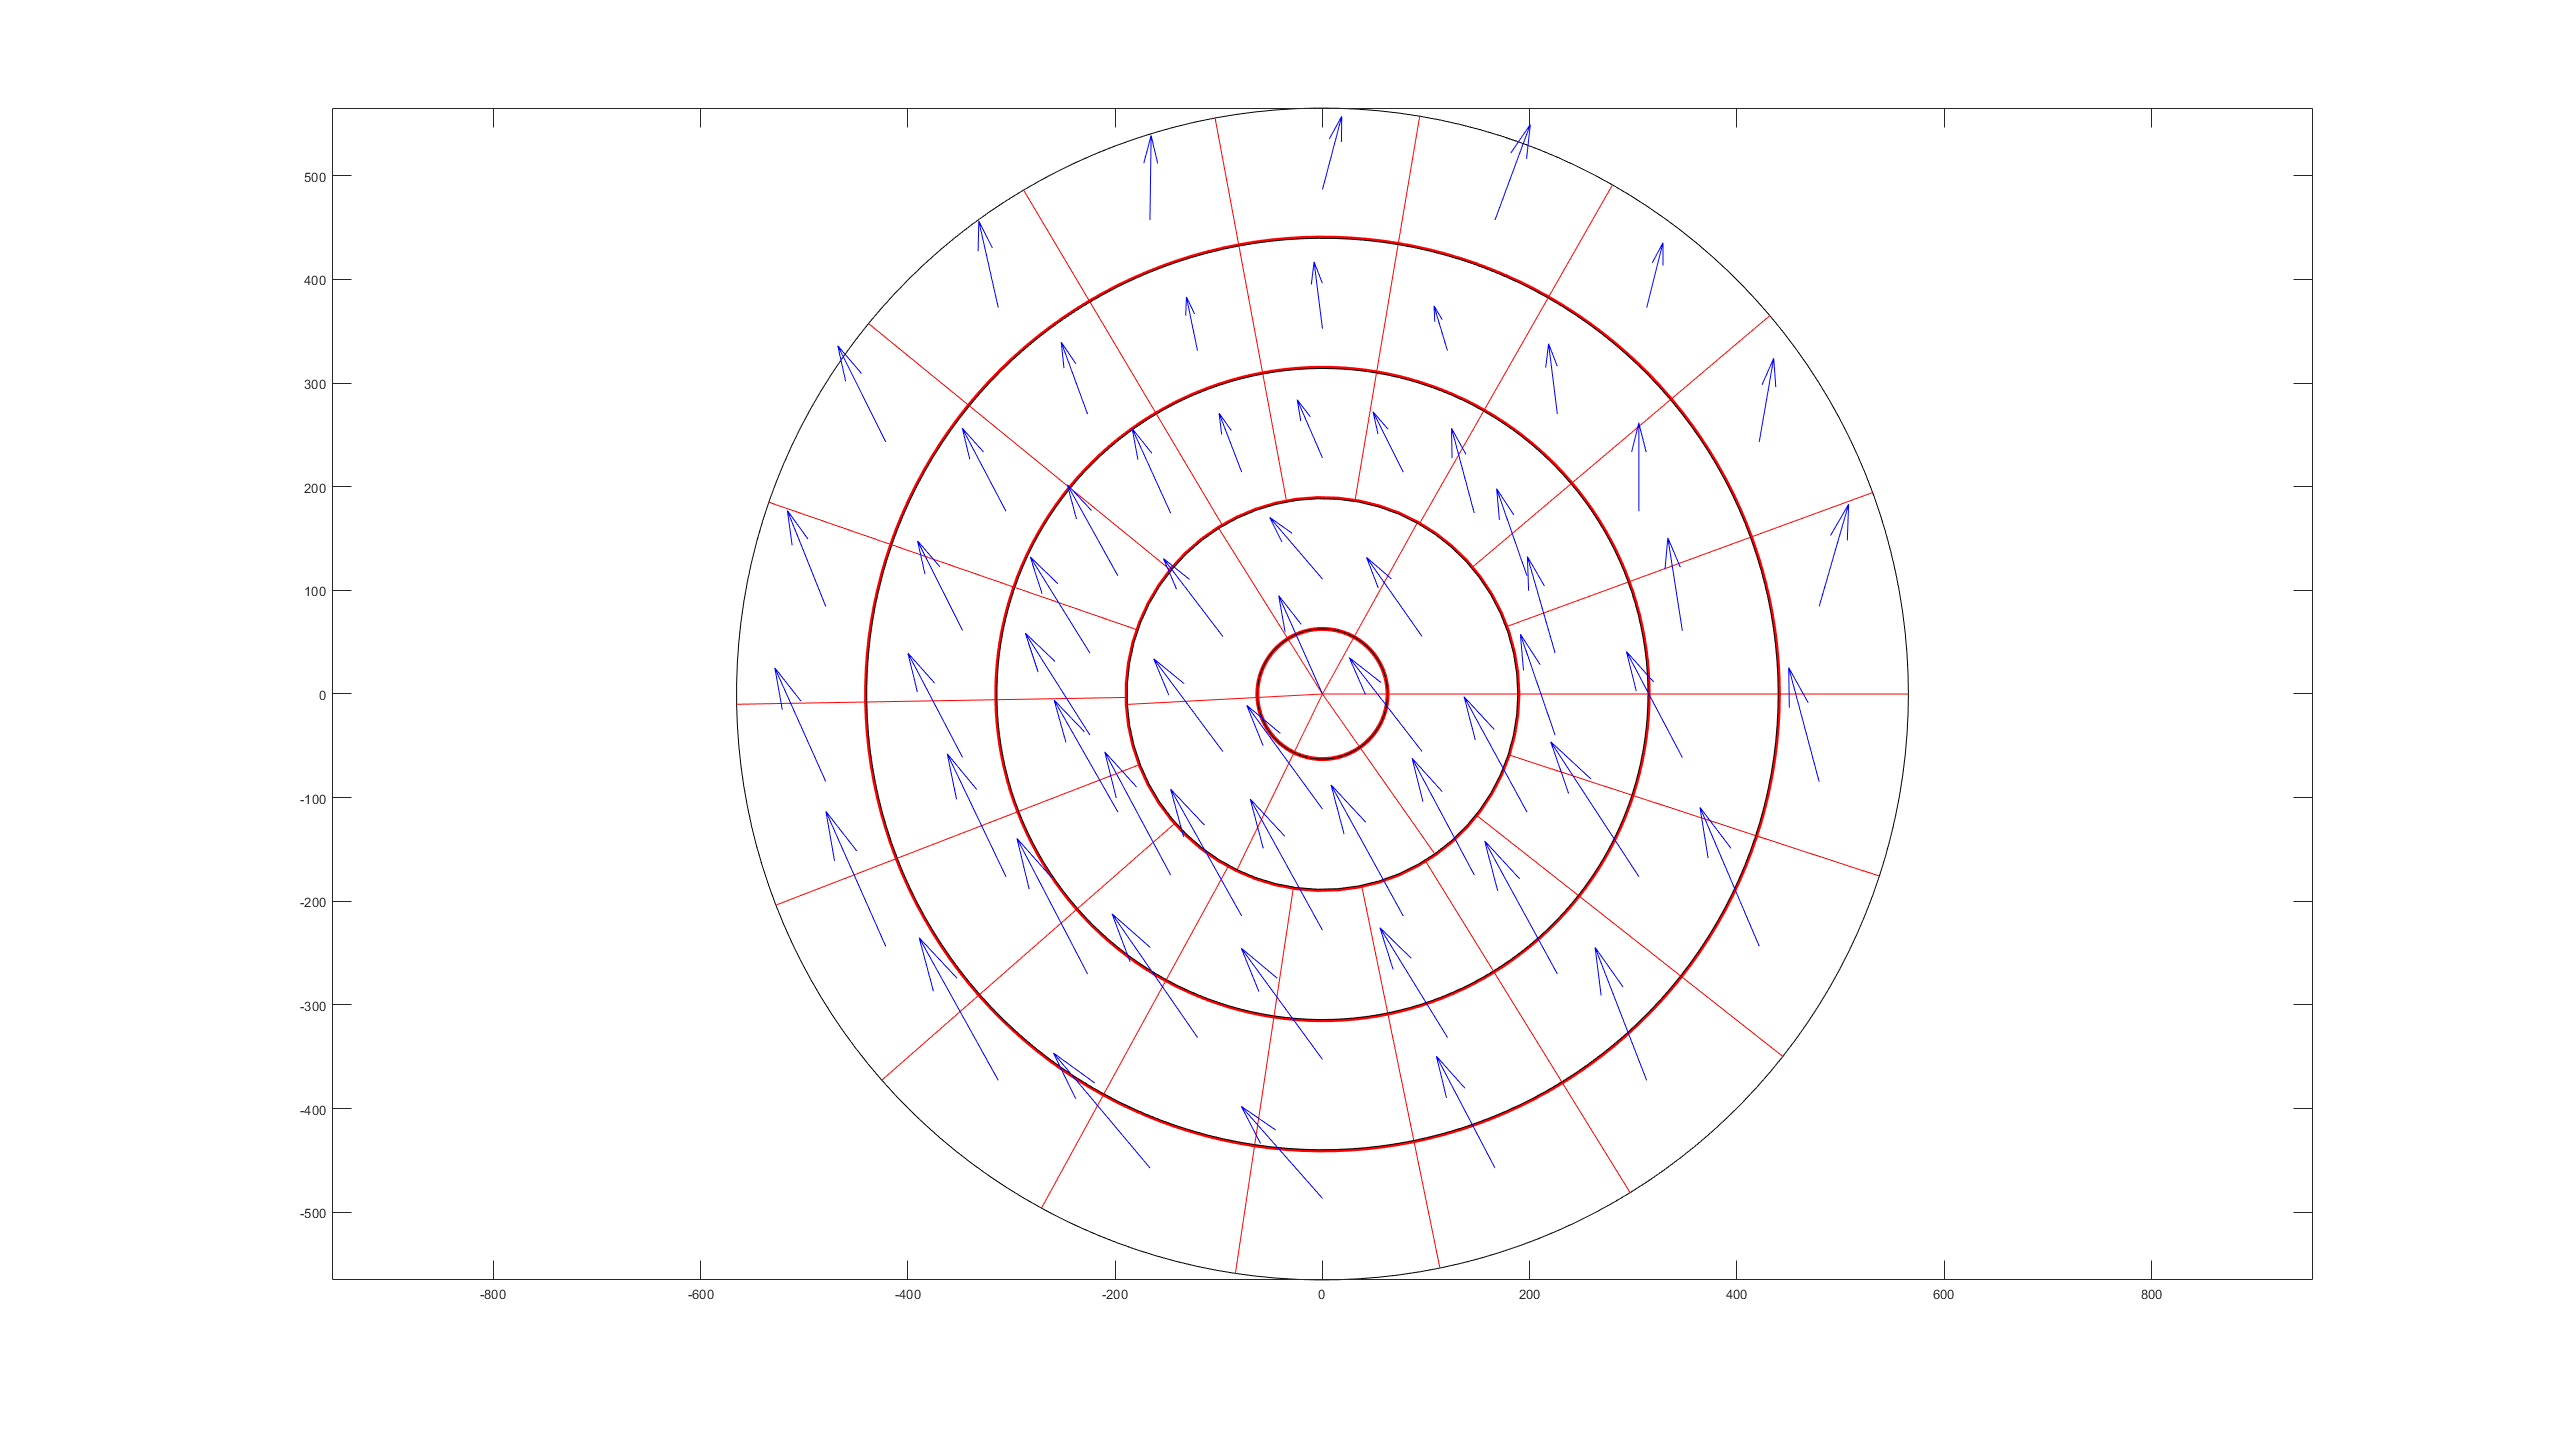

hold on
quiver(dz/1000,dm/1000,zonal,merid,"b")
hold off
axis on

%%%%%%%%%%%%%%%%%%
figure;
th = linspace(0,2*pi) ;   % angles 
r = [62.82272976
188.4681893
314.1136488
439.7591083
565.4045678
];        % redius of required circles 
fpi_loc = [16.0,78.1];              % cenre of the circle 
% 
for i = 1:length(r)
    % parametric equation of circles
    x = C(1)+r(i)*cos(th) ;
    y = C(2)+r(i)*sin(th) ;
    plot(x,y,'r') ;
    hold on    
end
axis equal
%%%%%%plot(C(1),C(2),'Xb') ;  % centre circle cross 
% Draw lines
% th1 = [pi/4 3*pi/4 5*pi/4 7*pi/4] ; % angles at which lines required 
th1 = deg2rad([60, 120,180,240,300,0])

th1 =        1.0472       2.0944       3.1416       4.1888        5.236            0


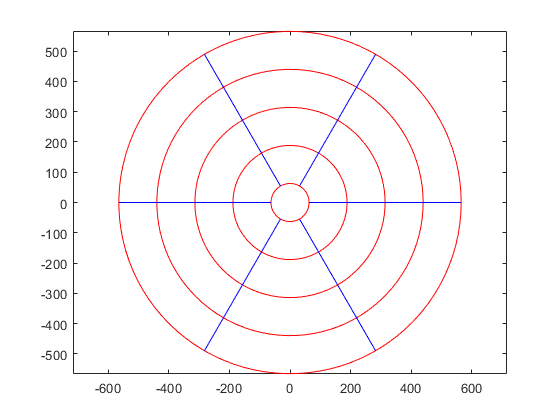

t = linspace(0,1) ;                     
% draw lines
for i = 1:length(th1)
    x0 = r(1)*cos(th1(i)) ; y0 = r(1)*sin(th1(i)) ;
    x2 = r(2)*cos(th1(i)) ; y2 = r(2)*sin(th1(i)) ;
    x1 = r(end)*cos(th1(i)) ; y1 = r(end)*sin(th1(i)) ;
    x = x0+t*(x1-x0) ;y = y0+t*(y1-y0) ; % parametric equation of line 
    %x = x0+t*(x2-x0) ;y = y0+t*(y2-y0) ;
    
    plot(x,y,'b')
end
axis on

%%%%%%%%%%%%%%%%%%
figure;
th = linspace(0,2*pi) ;   % angles 
r = [62.82272976
188.4681893
314.1136488
439.7591083
565.4045678
];        % redius of required circles 
C = [0,0];              % cenre of the circle 
% 
for i = 1:length(r)
    % parametric equation of circles
    x = C(1)+r(i)*cos(th) ;
    y = C(2)+r(i)*sin(th) ;
    plot(x,y,'r') ;
    hold on    
end
axis equal
%%%%%%plot(C(1),C(2),'Xb') ;  % centre circle cross 
% Draw lines
% th1 = [pi/4 3*pi/4 5*pi/4 7*pi/4] ; % angles at which lines required 
th1 = deg2rad([60, 120,180,240,300,0])

th1 =     1.0472    2.0944    3.1416    4.1888    5.2360         0


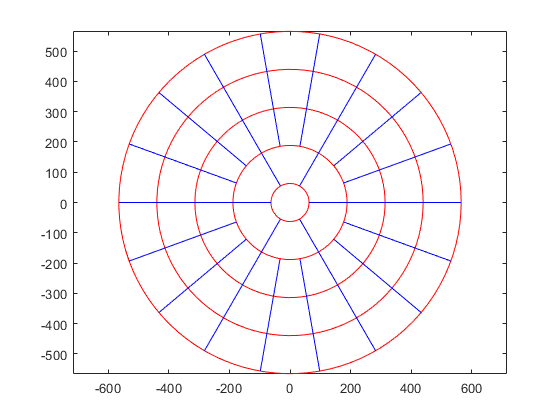

t = linspace(0,1) ;                     
% draw lines
for i = 1:length(th1)
    x0 = C(1)+r(1)*cos(th1(i)) ; y0 = C(2)+r(1)*sin(th1(i)) ;
    x2 = C(1)+r(2)*cos(th1(i)) ; y2 = C(2)+r(2)*sin(th1(i)) ;
    %x1 = r(end)*cos(th1(i)) ; y1 = r(end)*sin(th1(i)) ;
    %x = x0+t*(x1-x0) ;y = y0+t*(y1-y0) ; % parametric equation of line 
    x = x0+t*(x2-x0) ;y = y0+t*(y2-y0) ;
    patch(x,y,"r")
    plot(x,y,'b')
    
    hold on
end

th1 = deg2rad([60,80,100,120,140,160,180,200,220,240,260,280,300,320,340,0,20,40,60]);
t = linspace(0,1) ;                  
for i = 1:length(th1)
    x0 = r(1)*cos(th1(i)) ; y0 = r(1)*sin(th1(i)) ;
    x2 = r(2)*cos(th1(i)) ; y2 = r(2)*sin(th1(i)) ;
    x1 = r(end)*cos(th1(i)) ; y1 = r(end)*sin(th1(i)) ;
    %x = x0+t*(x1-x0) ;y = y0+t*(y1-y0) ; % parametric equation of line 
    x = x2+t*(x1-x2) ;y = y2+t*(y1-y2) ;
    
    plot(x,y,'b')
end
axis on

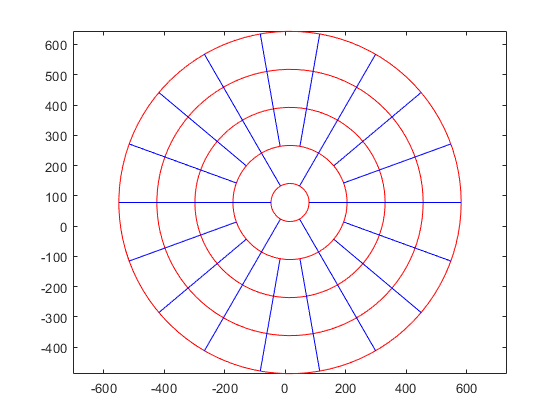

%%% Final SCANDI zones

r = [62.82272976
188.4681893
314.1136488
439.7591083
565.4045678
];

fpi_loc = [16.0,78.1];
Scandi_zones(fpi_loc,r)

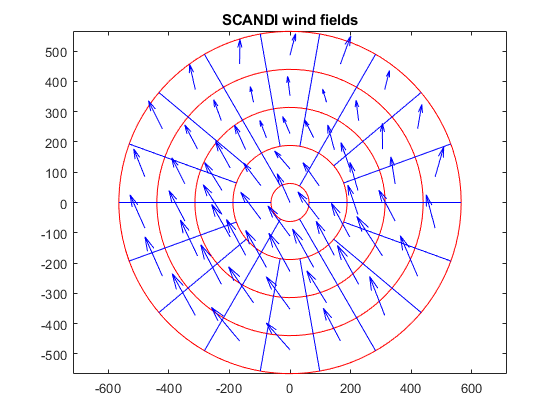

Scandi_zones([0,0],r)
hold on
quiver(dz/1000,dm/1000,zonal,merid,"b")
hold off
title("SCANDI wind fields")

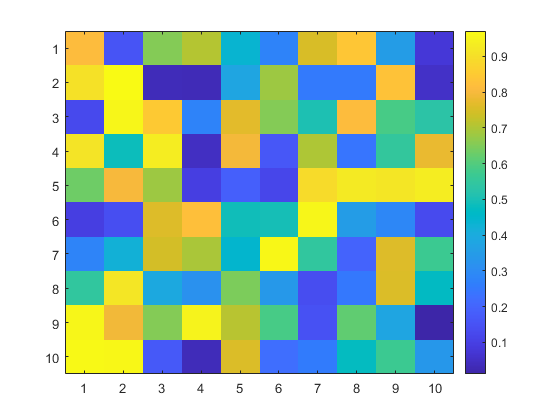

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% generating heat maps %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 

figure;
M = rand(10,10);
imagesc(M)
colorbar

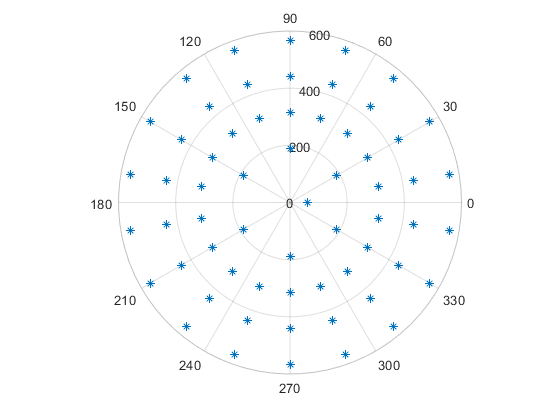

angle;
%%% create array of r values for 61 sectors
r1 = repmat(62.823,1);
r2 = repmat(188.468,6,1);
r3 = repmat(314.117,18,1);
r4 = repmat(439.759,18,1);
r5 = repmat(565.405,18,1);
r0 = cat(1,r1,r2,r3,r4,r5);
polarplot(deg2rad(angle),r0, "*")

figure;
th = linspace(0,pi/2)

th =          0    0.0159    0.0317    0.0476    0.0635    0.0793    0.0952    0.1111    0.1269    0.1428    0.1587    0.1745    0.1904    0.2063    0.2221    0.2380    0.2539    0.2697    0.2856    0.3015    0.3173    0.3332    0.3491    0.3649    0.3808    0.3967    0.4125    0.4284    0.4443    0.4601    0.4760    0.4919    0.5077    0.5236    0.5395    0.5553    0.5712    0.5871    0.6029    0.6188    0.6347    0.6505    0.6664    0.6823    0.6981    0.7140    0.7299    0.7457    0.7616    0.7775


r = repmat(68.8,length(th),1);

r =    68.8000
   68.8000
   68.8000
   68.8000
   68.8000
   68.8000
   68.8000
   68.8000
   68.8000
   68.8000


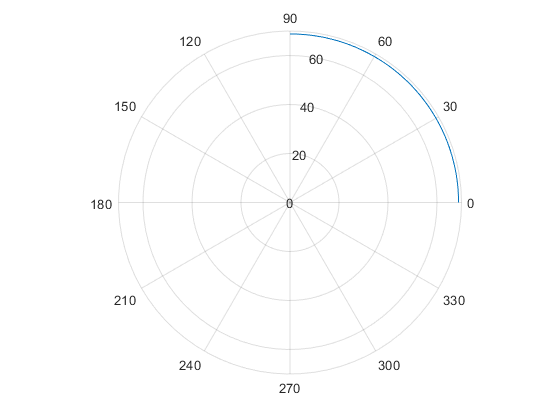

polarplot(th,r)

%%%

n = 6;
r = [0.8; 1];
theta = pi*(-n:0.8*n)/n;

theta =          0    0.0159    0.0317    0.0476    0.0635    0.0793    0.0952    0.1111    0.1269    0.1428    0.1587    0.1745    0.1904    0.2063    0.2221    0.2380    0.2539    0.2697    0.2856    0.3015    0.3173    0.3332    0.3491    0.3649    0.3808    0.3967    0.4125    0.4284    0.4443    0.4601    0.4760    0.4919    0.5077    0.5236    0.5395    0.5553    0.5712    0.5871    0.6029    0.6188    0.6347    0.6505    0.6664    0.6823    0.6981    0.7140    0.7299    0.7457    0.7616    0.7775


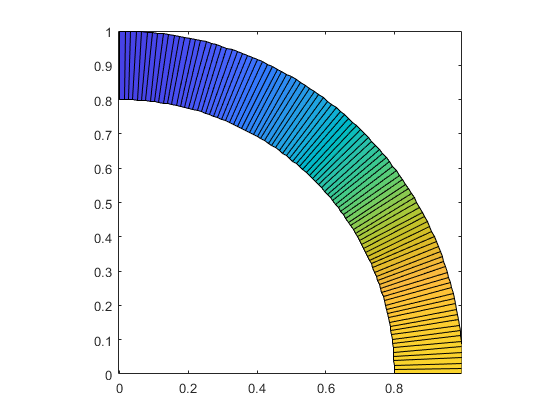

X = r*cos(theta);
Y = r*sin(theta);
C = r*cos(2*theta);
pcolor(X,Y,C)
axis equal tight